data= load('\\fs.ista.ac.at\group\joeschgrp\Group Members\Rima\Aggregated\AnimalRB6_250302_1656_preprocessed.mat');

## plotting Positioning of ROIs

%extract ROI position (both planes here)
centroid = data.CaData(1).Ca_centroid_voxel;
centroidX = centroid(:, 1);
centroidY = centroid(:, 2);
centroidZ = centroid(:, 3);

figure;
scatter(centroidY, centroidX)
set(gca, 'YDir', 'reverse'); % This inverts the y-axis

## Normalising Calcium Activity

dFF = data.CaData(1).Ca_dFF;

%different normalisations 

%normalize by min&max - worst 
%dFF_norm = (dFF - min(dFF,[],2)) ./ (max(dFF,[],2) - min(dFF,[],2)); 
%-zsocre
dFF_z = (dFF - mean(dFF, 2)) ./ std(dFF, 0, 2); 
% 0 to max normalisation 
dFF_norm = (dFF - min(dFF,[],2)) ./ (max(dFF,[],2) - min(dFF,[],2)) .* max(dFF,[],2);
% mean normlisation 
dFF_norm_mean = dFF ./ mean(dFF, 2);

## Plotting Heatmap of Calcium Activity

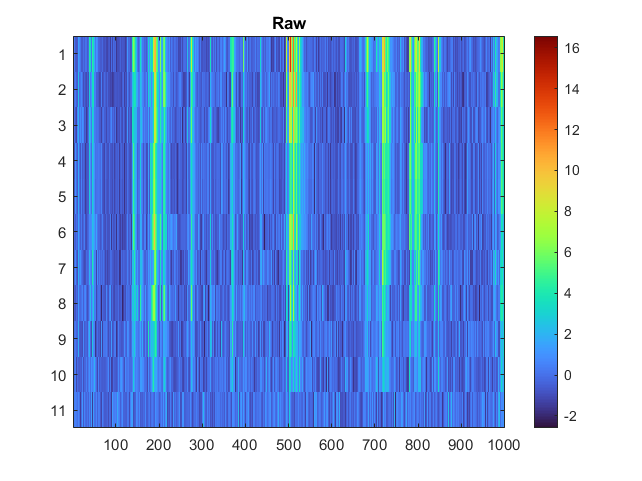


roi_indices = (1:11); %ALL ROIs  
%roi_indices = setdiff(1:11, 3); % All ROIs from 1 to 11 except 3

dFF_selected = dFF(roi_indices, 3000:4000);
%dFF_norm_selected = dFF_norm(roi_indices, 3000:4000); 
dFF_z_selected = dFF_z(roi_indices, 3000:4000);
dFF_norm_selected = dFF_norm(roi_indices, 3000:4000);
dFF_norm_mean_selected = dFF_norm_mean(roi_indices, 3000:4000);

%sort ROIs by maximum
[~, sort_idx] = sort(max(dFF_selected, [], 2), 'descend'); % Change to 'ascend' if you want lowest to highest

dFF_selected = dFF_selected(sort_idx, :);
%dFF_norm_selected = dFF_norm_selected(sort_idx, :);
dFF_z_selected = dFF_z_selected(sort_idx, :);
dFF_norm_selected = dFF_norm_selected(sort_idx, :);
dFF_norm_mean_selected = dFF_norm_mean_selected(sort_idx, :);

original_colormap = gray;  % Get the default gray colormap
reversed_colormap = flipud(original_colormap);

figure;
imagesc(dFF_selected)
title("Raw")
colormap('turbo'); % Use a colormap like 'hot' or 'jet'
colorbar;  % Add a color scale

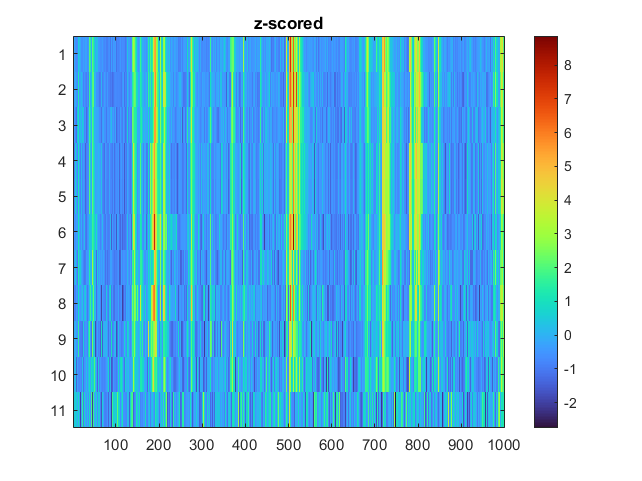


figure;
imagesc(dFF_z_selected)
title("z-scored")
colormap('turbo'); 
colorbar;  % Add a color scale

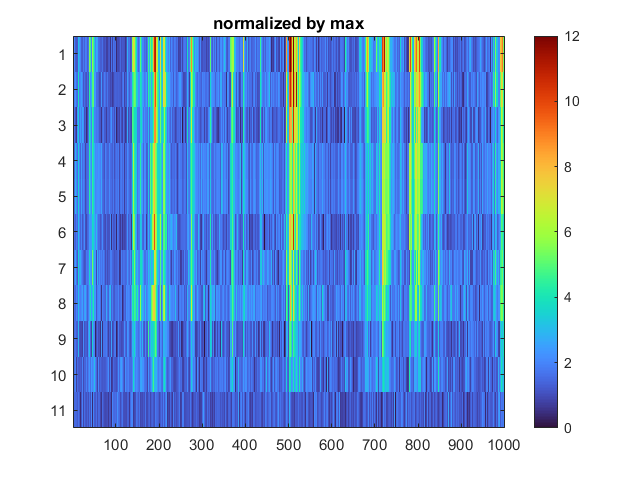


figure;
imagesc(dFF_norm_selected)
title("normalized by max")
colormap(turbo); 
colorbar;
c = colorbar;  % Add a color scale
caxis([0 12]); % Adjust as needed based on the range of your data

## Aligning Calcium Activity with Behaviour

Plot Calcium Activity traces with pupil dynamics and locomotion 

% calcium activity is aligned to the stimulus using the same time vector 
% Get stimulus timing
stim_total_time = data.Stimuli(2).stimulus_trial_t * data.Stimuli(2).trials

stim_total_time = 150

stim_start = data.Stimuli(2).TimeStimulusFrame(1)

stim_start = 255.1106

stim_end = stim_start + stim_total_time

stim_end = 405.1106

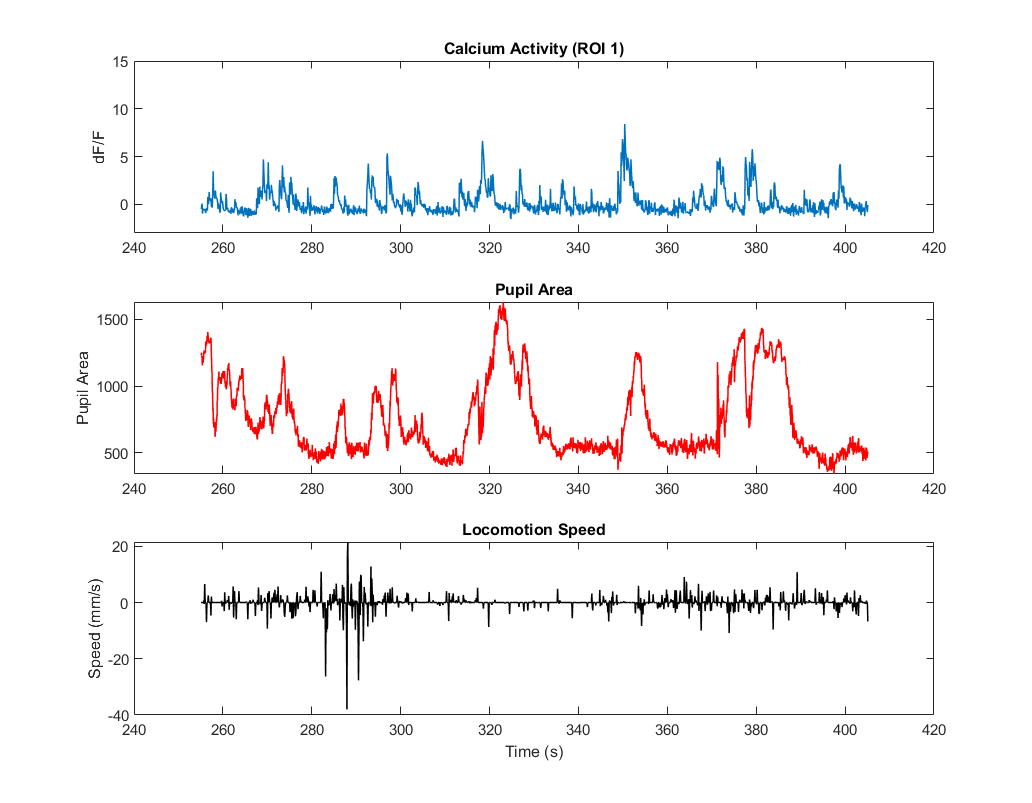


% Find frames of calcium for defined stimulus timing
Ca_index = find(data.TimeCa(1, :) > stim_start & data.TimeCa(1, :) < stim_end);
Ca_selected = dFF_z(:,Ca_index);

% Find behavior data for defined stimulus timing
Beh_index = find(data.Triggers.TimeCamera > stim_start & data.Triggers.TimeCamera < stim_end);
Beh_selected = data.Behav.PupilArea(Beh_index);

% Find locomotion data for defined stimulus timing
Loc_index = find(data.Triggers.TimeBall{4, 1} > stim_start & data.Triggers.TimeBall{4, 1} < stim_end);
Loc_time = data.Triggers.TimeBall{4, 1}(Loc_index); % Extract timestamps
Loc_position = data.LocomotionCal(1).Forward_mm(Loc_index); % Extract position

% Compute locomotion speed (mm/s)
Loc_velocity = diff(Loc_position) ./ diff(Loc_time); 
Loc_time_velocity = Loc_time(1:end-1); % Adjust time vector for velocity

% Create time vector
time_vector = linspace(stim_start, stim_end, size(Ca_selected,2));

figure;

% Plot calcium data (first ROI only)
subplot(3,1,1);
plot(time_vector, Ca_selected(4,:), 'LineWidth', 1);
title('Calcium Activity (ROI 1)');
ylabel('dF/F');
ylim([-3 15]);
ax1 = gca; % Save axis handle for linking

% Plot behavioral data (Pupil Area)
subplot(3,1,2);
plot(linspace(stim_start, stim_end, length(Beh_selected)), Beh_selected, 'r', 'LineWidth', 1);
title('Pupil Area');
ylabel('Pupil Area');
ax2 = gca; % Save axis handle for linking

% Interpolate locomotion velocity to match calcium time vector
Loc_velocity_resampled = interp1(Loc_time_velocity, Loc_velocity, time_vector, 'linear', 'extrap');

% Plot locomotion speed
subplot(3,1,3);
plot(time_vector, Loc_velocity_resampled, 'k', 'LineWidth', 1);
title('Locomotion Speed');
xlabel('Time (s)');
ylabel('Speed (mm/s)');
ax3 = gca; % Save axis handle for linking

% Link the x-axes so they zoom/pan together
linkaxes([ax1, ax2, ax3], 'x');

% Adjust spacing and figure size
set(gcf, 'Position', [100, 100, 900,700]); % Make figure larger

## Generating fff_stimulus 

ifi = data.Stimuli(1).ifi(1) 

ifi = 0.0167

stim_start = data.Stimuli(2).TimeStimulusFrame(1);
options = data.Stimuli(2);%.specParams;


[fff_brightness, single_pulse] = mk_fff_curve(options, ifi, stim_start);


Aligning Calcium Data with locomotion and Pupil 

% Get stimulus timing for a particular stimulus
stim_idx = 2;
roi_id=4;
roi_plane=data.CaData(1).Ca_centroid_voxel(roi_id,3);
stim_total_time = data.Stimuli(stim_idx).stimulus_trial_t * data.Stimuli(stim_idx).trials

stim_total_time = 150

stim_start = data.Stimuli(stim_idx).TimeStimulusFrame(1)

stim_start = 255.1106

stim_end = stim_start + stim_total_time

stim_end = 405.1106

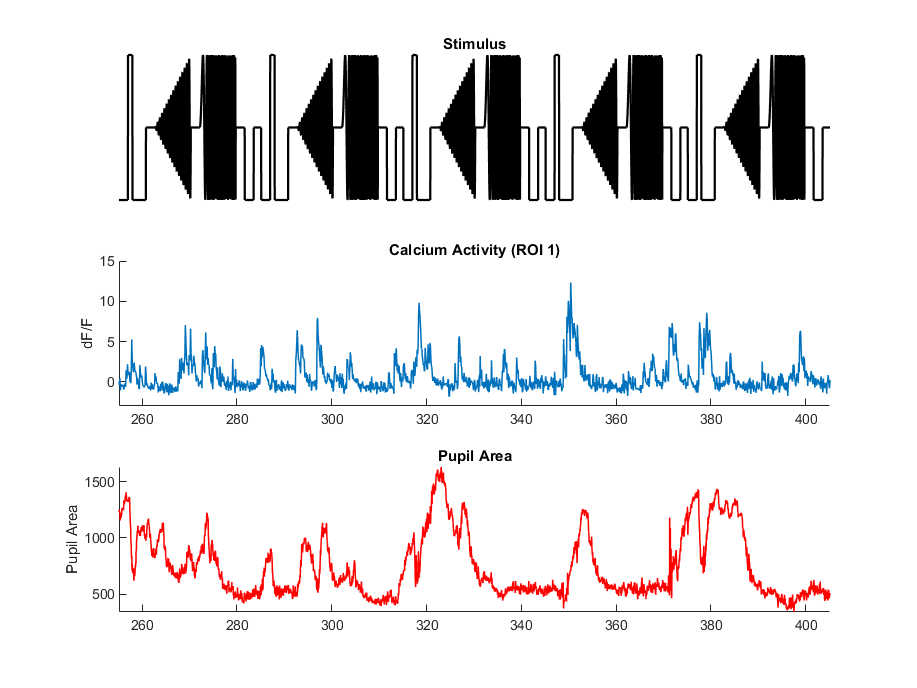


% Find frames of calcium for defined stimulus timing
Ca_index = find(data.TimeCa(roi_plane, :) > stim_start & data.TimeCa(roi_plane, :) < stim_end);
Ca_selected = data.CaData(roi_plane).Ca_dFF(:, Ca_index);

% Find behavior data for defined stimulus timing
Beh_index = find(data.Triggers.TimeCamera > stim_start & data.Triggers.TimeCamera < stim_end);
Beh_selected = data.Behav.PupilArea(Beh_index);

% Find locomotion data for defined stimulus timing
 Loc_index = find(data.Triggers.TimeBall{stim_idx *2} > stim_start & data.Triggers.TimeBall{stim_idx *2} < stim_end);
 Loc_time = data.Triggers.TimeBall{stim_idx *2}(Loc_index); % Extract timestamps
 Loc_position = data.LocomotionCal(1).Forward_mm(Loc_index); % Extract position

% Compute locomotion speed (mm/s), handling edge case
if length(Loc_time) > 1
    Loc_velocity = diff(Loc_position) ./ diff(Loc_time); 
    Loc_time_velocity = Loc_time(1:end-1); % Adjust time vector for velocity
else
    Loc_velocity = zeros(1, length(Loc_time)); % Prevent errors
    Loc_time_velocity = Loc_time;
end

% Create time vector for consistent x-axis across all plots
time_vector = linspace(stim_start, stim_end, size(Ca_selected,2));

% Create figure for Stimulus 2
figure('Name', 'Stimulus 2');

%plot the stimulus
subplot(3,1,1);
num_repeats = 5;  % Number of stimulus repetitions
fff_brightness_repeated = repmat(fff_brightness, 1, num_repeats); 
plot(linspace(stim_start, stim_end, length(fff_brightness_repeated)), fff_brightness_repeated, 'k', 'LineWidth', 1.5);
title ("Stimulus")
axis off; 
set(gca, 'Box', 'off');          
xlim([stim_start, stim_end])
        

% Plot calcium data (1 ROI only)
subplot(3,1,2);
plot(time_vector, Ca_selected(roi_id,:), 'LineWidth', 1);
title('Calcium Activity (ROI 1)');
ylabel('dF/F');
ylim([-3 15]);
set(gca, 'Box', 'off');  
xlim([stim_start, stim_end])

% Plot behavioral data (Pupil Area)
subplot(3,1,3);
plot(linspace(stim_start, stim_end, length(Beh_selected)), Beh_selected, 'r', 'LineWidth', 1);
title('Pupil Area');
ylabel('Pupil Area');
set(gca, 'Box', 'off');  
xlim([stim_start, stim_end])

% Interpolate locomotion velocity to match calcium time vector
if length(Loc_time_velocity) > 1
    Loc_velocity_resampled = interp1(Loc_time_velocity, Loc_velocity, time_vector, 'linear', 'extrap');
else
    Loc_velocity_resampled = zeros(size(time_vector)); % No movement case
end

% % Plot locomotion speed
% subplot(4,1,4);
% plot(time_vector, Loc_velocity_resampled, 'k', 'LineWidth', 1);
% title('Locomotion Speed');
% xlabel('Time (s)');
% ylabel('Speed (mm/s)');
% ax3 = gca; % Save axis handle for linking

% Link the x-axes so they zoom/pan together

% Adjust spacing and figure size
set(gcf, 'Position', [100, 100, 800, 600]); % Make figure larger

Chunking data by trial 

num_trials = data.Stimuli.trials

num_trials = 5

no_stimuli = 4;
chunk_size = length(data.Stimuli(1).TimeStimulusFrame)/num_trials;

for idx = 1:no_stimuli 
    for no_trial = 1:num_trials
      desired_vector = data.Stimuli(idx).TimeStimulusFrame;
      desired_vector = desired_vector(chunk_size * (no_trial -1) + 1 : chunk_size * no_trial);
      data.Stimuli(idx).TrialTimes{no_trial} = desired_vector;
    end
end


num_stimuli = length(data.Stimuli); % Number of stimuli
trial_number = 5;  %number of trials 

for stim_idx = 1:num_stimuli
    for trial_times =1:trial_number
        % Get stimulus timing
        trial_time = data.Stimuli(stim_idx).stimulus_trial_t;
        stim_start = data.Stimuli(stim_idx).TrialTimes{1, trial_times}(1);
        stim_end = stim_start + trial_time;
    
        % Find frames of calcium for defined stimulus timing
        Ca_index = find(data.TimeCa(1, :) > stim_start & data.TimeCa(1, :) < stim_end);
        Ca_selected = data.CaData(1).Ca_dFF(4, Ca_index);
        
    end
end 

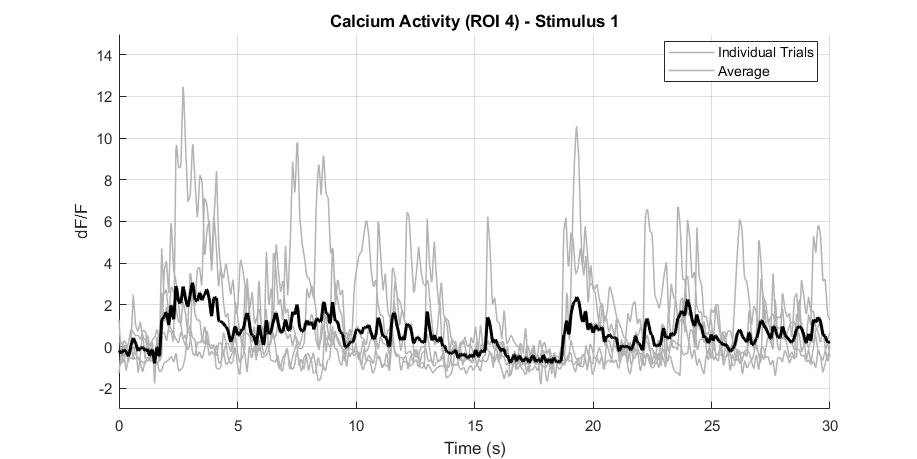

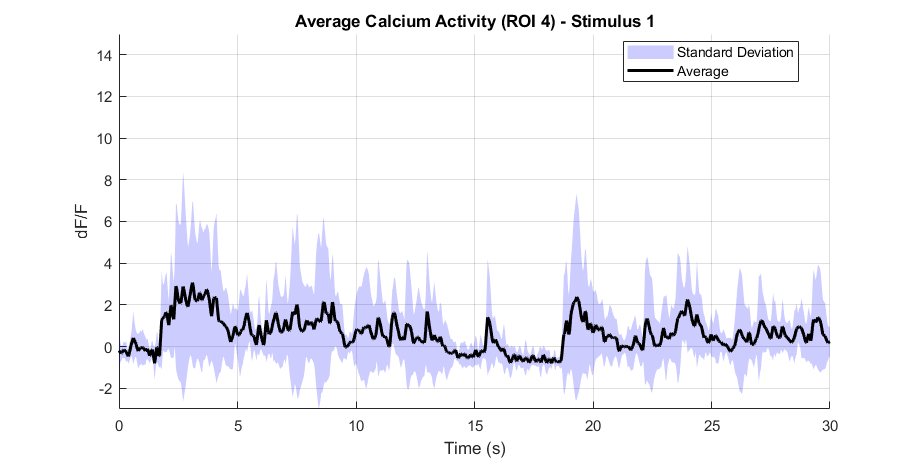

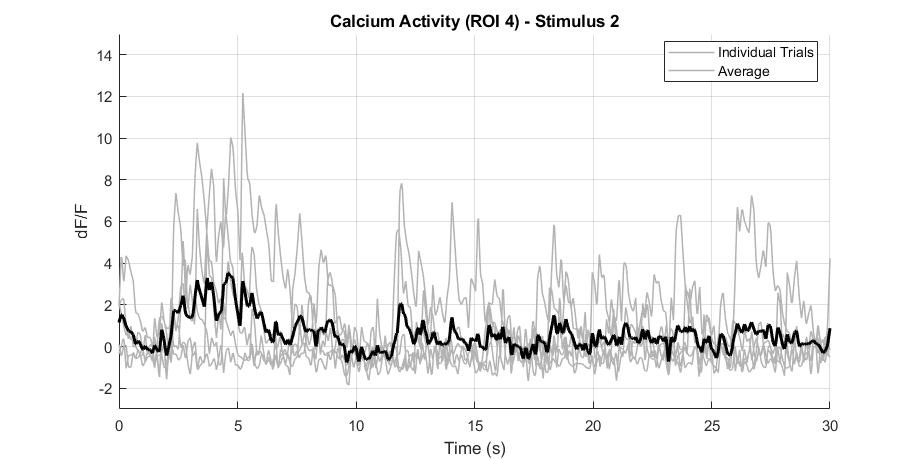

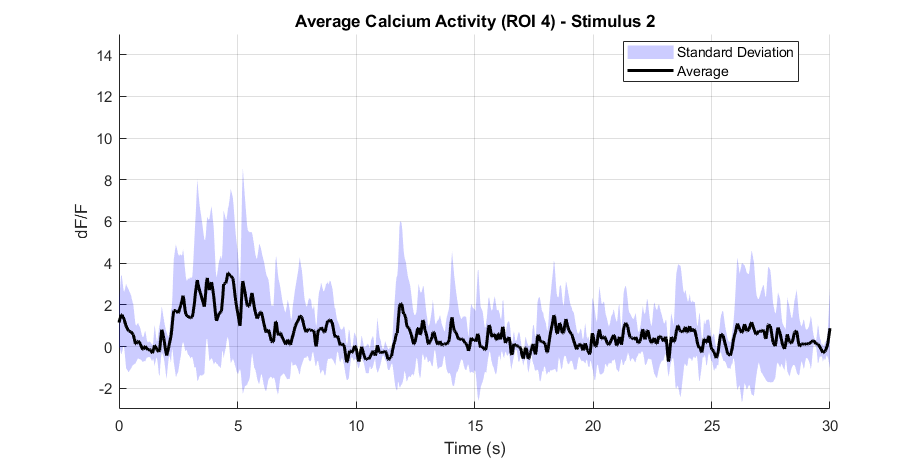

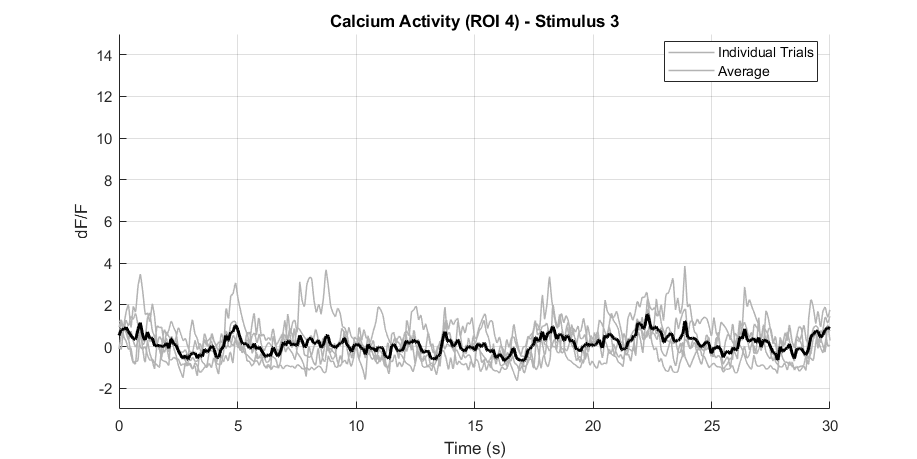

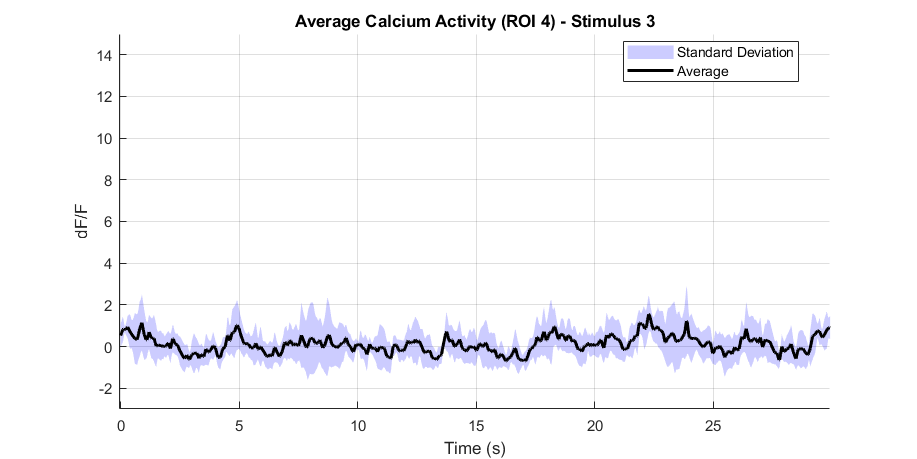

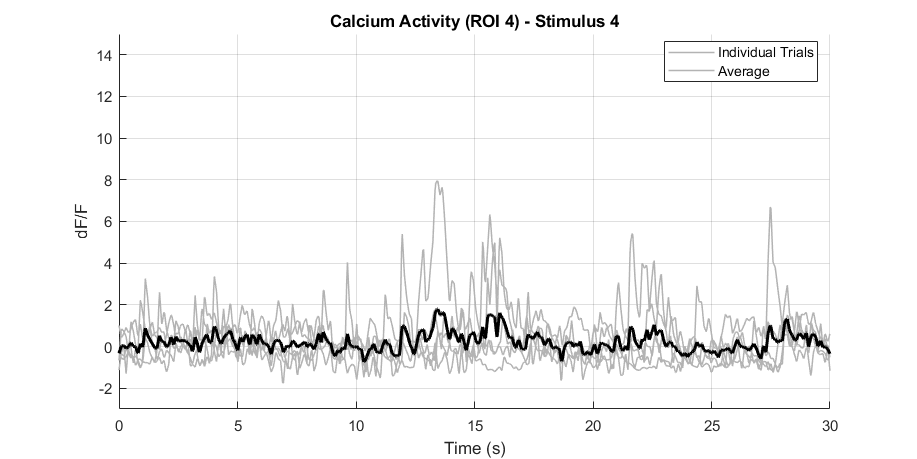

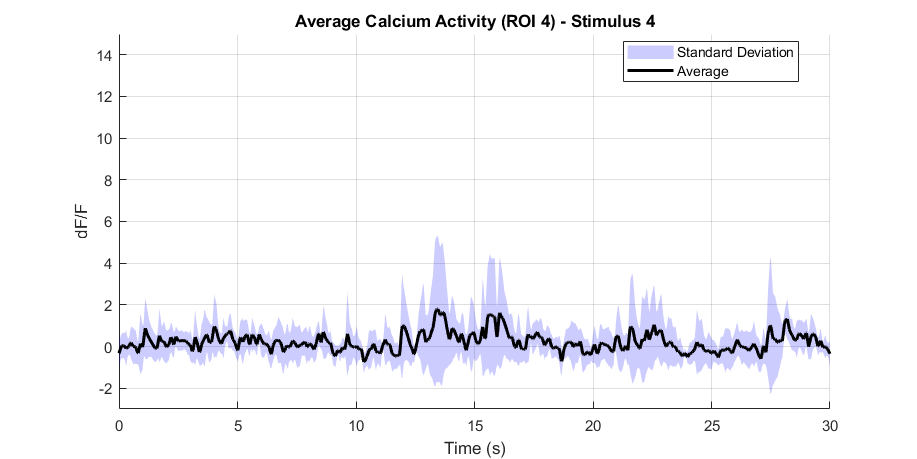

% Generate two plots for each stimulus:
% 1) All trials in grey with average in black
% 2) Average with standard deviation cloud

num_stimuli = length(data.Stimuli); % Number of stimuli
trial_number = 5;  % number of trials 
roi_number = 4;    % ROI number to plot

% Create figures for each stimulus
for stim_idx = 1:num_stimuli
    % Storage for all trials to calculate average later
    all_trials_ca = cell(1, trial_number);
    all_trials_time = cell(1, trial_number);
    
    % First collect all trials for this stimulus
    for trial_times = 1:trial_number
        % Get stimulus timing
        trial_time = data.Stimuli(stim_idx).stimulus_trial_t;
        stim_start = data.Stimuli(stim_idx).TrialTimes{1, trial_times}(1);
        stim_end = stim_start + trial_time;
    
        % Find frames of calcium for defined stimulus timing
        Ca_index = find(data.TimeCa(1, :) > stim_start & data.TimeCa(1, :) < stim_end);
        Ca_selected = data.CaData(1).Ca_dFF(roi_number, Ca_index);
        
        % Create time vector for this trial
        time_vector = linspace(0, trial_time, length(Ca_selected));
        
        % Store data for averaging later
        all_trials_ca{trial_times} = Ca_selected;
        all_trials_time{trial_times} = time_vector;
    end
    
    % Create a common time vector for resampling
    common_time = linspace(0, trial_time, 1000); % 1000 points for smooth curve
    resampled_ca = zeros(trial_number, length(common_time));
    
    % Resample all trials to common time base
    for trial_times = 1:trial_number
        resampled_ca(trial_times, :) = interp1(all_trials_time{trial_times}, all_trials_ca{trial_times}, common_time, 'linear', 'extrap');
    end
    
    % Calculate average and standard deviation across trials
    avg_ca = mean(resampled_ca, 1);
    std_ca = std(resampled_ca, 0, 1);
    
    % Calculate upper and lower bounds for shaded area
    upper_bound = avg_ca + std_ca;
    lower_bound = avg_ca - std_ca;
    
    %% PLOT 1: All trials in grey with average in black
    figure('Name', sprintf('Calcium Activity - All Trials - Stimulus %d', stim_idx));
    hold on;
    
    % Plot each trial in grey
    for trial_times = 1:trial_number
        plot(common_time, resampled_ca(trial_times, :), 'Color', [0.7 0.7 0.7], 'LineWidth', 1);
    end
    
    % Plot average in thick black line
    plot(common_time, avg_ca, 'k', 'LineWidth', 2);
    
    % Add labels and title
    xlabel('Time (s)');
    ylabel('dF/F');
    title(sprintf('Calcium Activity (ROI %d) - Stimulus %d', roi_number, stim_idx));
    
    % Add legend
    legend('Individual Trials', 'Average', 'Location', 'best');
    
    % Set axes limits and appearance
    ylim([-3 15]);  % Based on your previous code
    set(gca, 'Box', 'off');
    grid on;
    
    % Adjust spacing and figure size
    set(gcf, 'Position', [100, 100, 800, 400]);
    
%     %% PLOT 2: Average with standard deviation cloud
%     figure('Name', sprintf('Average Calcium Activity - Stimulus %d', stim_idx));
%     hold on;
%     
%     % Create shaded area for standard deviation
%     x_shade = [common_time, fliplr(common_time)];
%     y_shade = [upper_bound, fliplr(lower_bound)];
%     
%     % Plot the shaded area
%     fill(x_shade, y_shade, 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
%     
%     % Plot average in thick black line
%     plot(common_time, avg_ca, 'k', 'LineWidth', 2);
%     
%     % Add labels and title
%     xlabel('Time (s)');
%     ylabel('dF/F');
%     title(sprintf('Average Calcium Activity (ROI %d) - Stimulus %d', roi_number, stim_idx));
%     
%     % Add legend
%     legend('Standard Deviation', 'Average', 'Location', 'best');
%     
%     % Set axes limits and appearance
%     ylim([-3 15]);  % Based on your previous code
%     set(gca, 'Box', 'off');
%     grid on;
%     
%     % Adjust spacing and figure size
%     set(gcf, 'Position', [100, 100, 800, 400]);
end

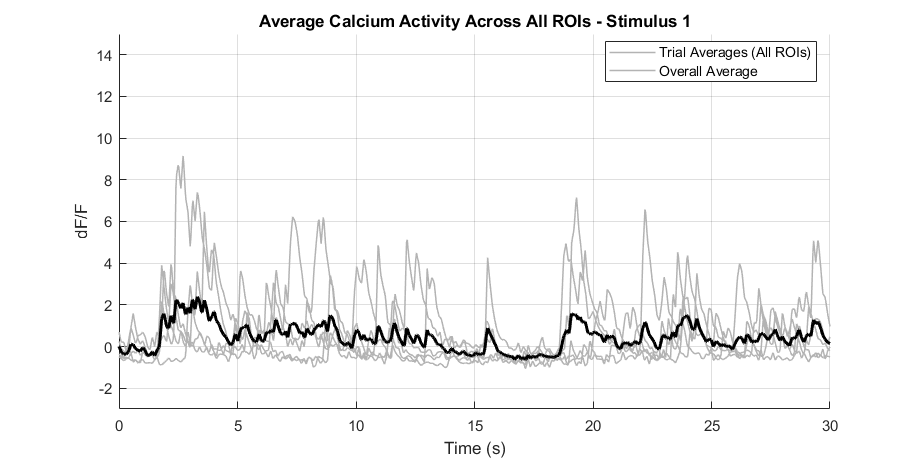

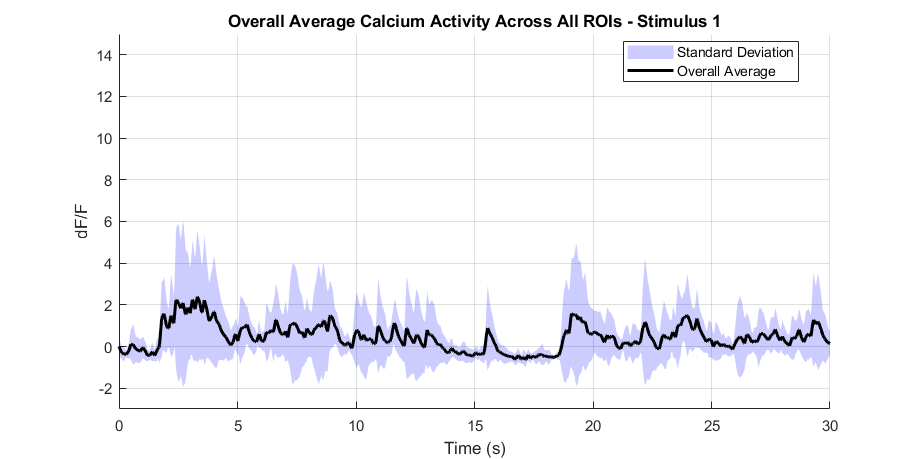

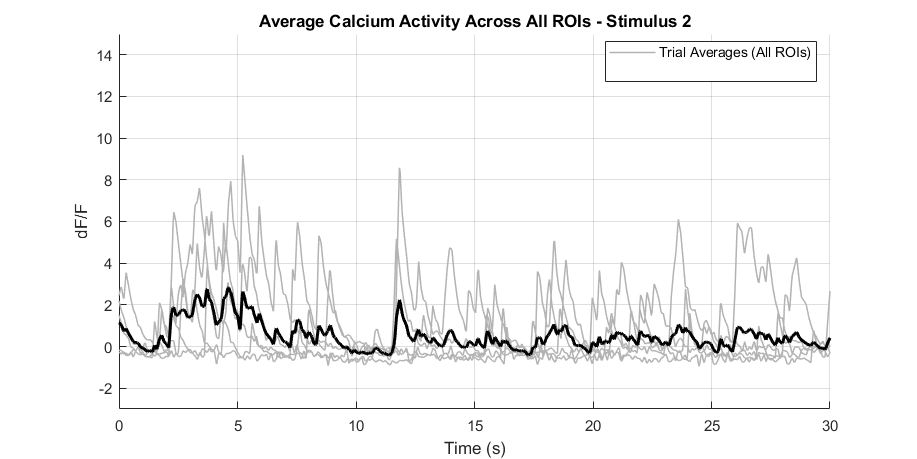

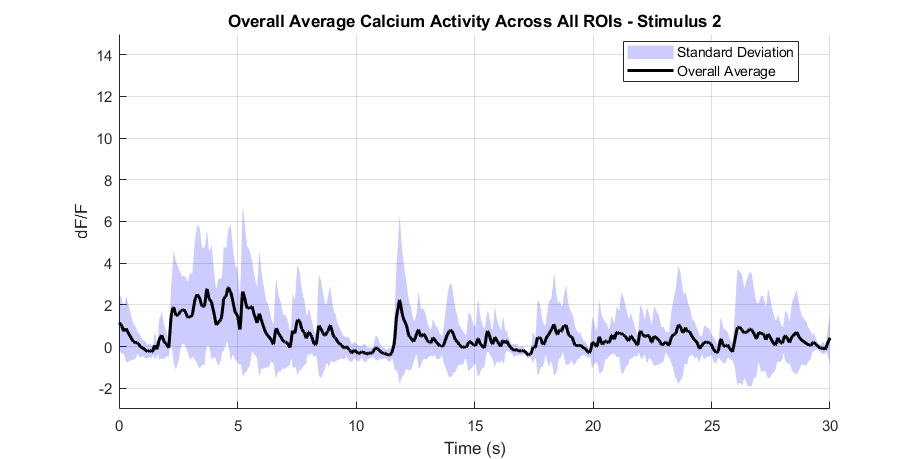

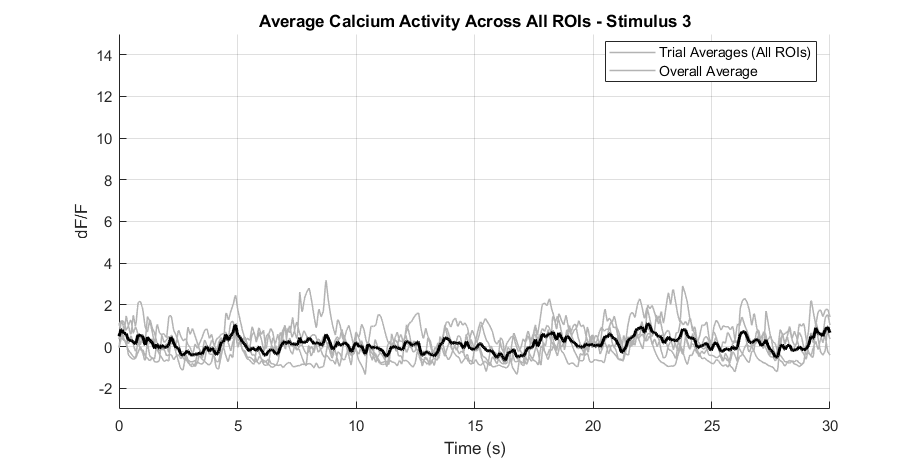

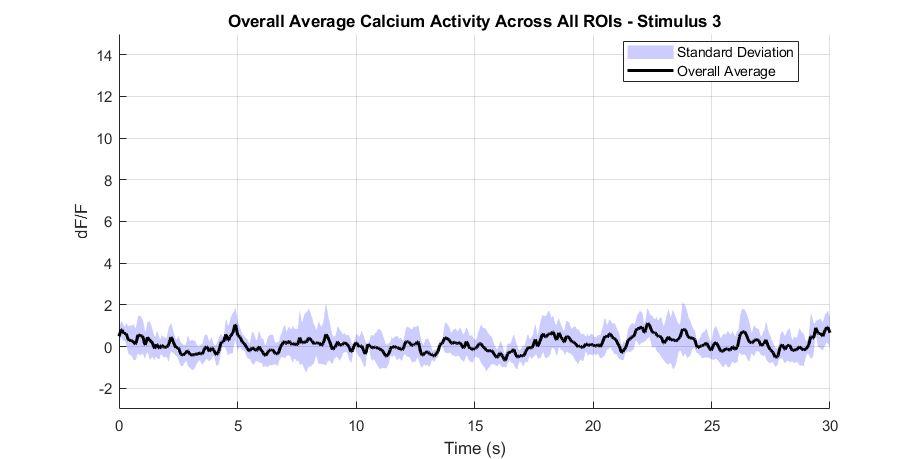

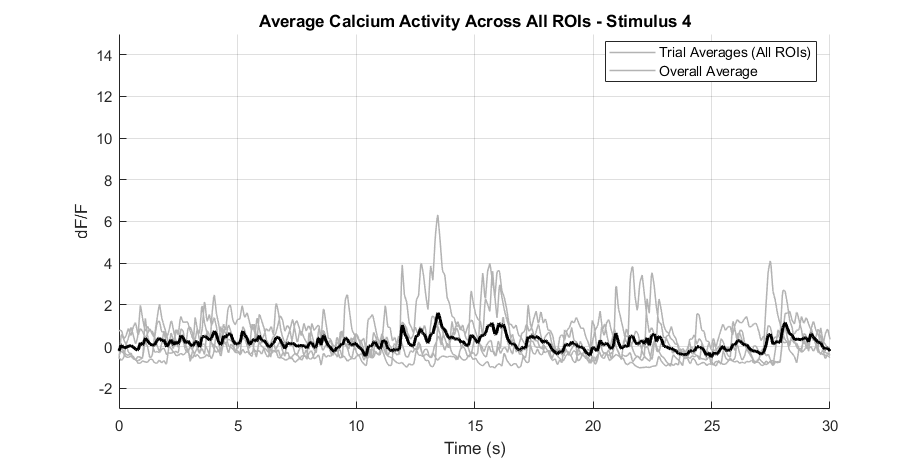

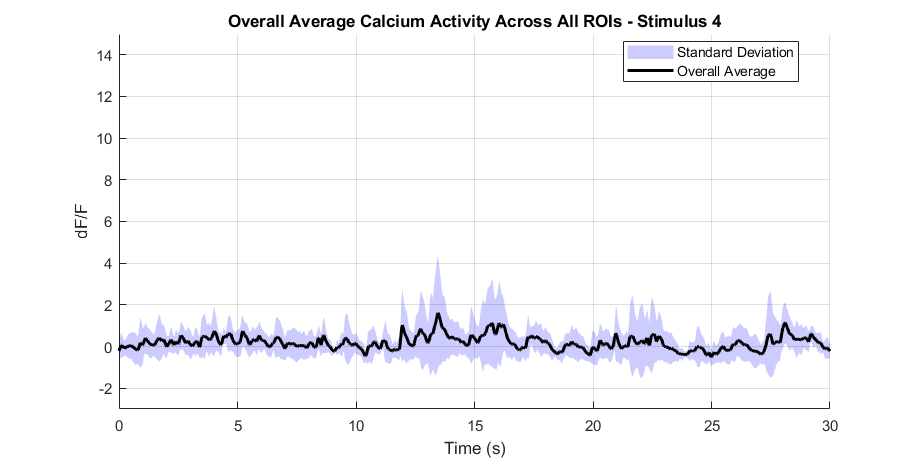


% Generate two plots for each stimulus:
% 1) Average of all ROIs for each trial (in grey) with overall average in black
% 2) Overall average with standard deviation cloud

num_stimuli = length(data.Stimuli); % Number of stimuli
trial_number = 5;  % number of trials 

% Get total number of ROIs from the data structure
num_rois = size(data.CaData(1).Ca_dFF, 1);

% Create figures for each stimulus
for stim_idx = 1:num_stimuli
    % Storage for trial averages (each trial being an average across all ROIs)
    trial_averages = cell(1, trial_number);
    all_trials_time = cell(1, trial_number);
    
    % First calculate the average across all ROIs for each trial
    for trial_times = 1:trial_number
        % Get stimulus timing
        trial_time = data.Stimuli(stim_idx).stimulus_trial_t;
        stim_start = data.Stimuli(stim_idx).TrialTimes{1, trial_times}(1);
        stim_end = stim_start + trial_time;
    
        % Find frames of calcium for defined stimulus timing
        Ca_index = find(data.TimeCa(1, :) > stim_start & data.TimeCa(1, :) < stim_end);
        
        % Get calcium data for all ROIs for this trial
        Ca_all_rois = data.CaData(1).Ca_dFF(:, Ca_index);
        
        % Calculate average across all ROIs for this trial
        Ca_trial_avg = mean(Ca_all_rois, 1);
        
        % Create time vector for this trial
        time_vector = linspace(0, trial_time, length(Ca_trial_avg));
        
        % Store the ROI-averaged data for this trial
        trial_averages{trial_times} = Ca_trial_avg;
        all_trials_time{trial_times} = time_vector;
    end
    
    % Create a common time vector for resampling
    common_time = linspace(0, trial_time, 1000); % 1000 points for smooth curve
    
    % Resample all trial averages to common time base
    resampled_trial_avgs = zeros(trial_number, length(common_time));
    for trial_times = 1:trial_number
        resampled_trial_avgs(trial_times, :) = interp1(all_trials_time{trial_times}, ...
            trial_averages{trial_times}, common_time, 'linear', 'extrap');
    end
    
    % Calculate overall average and standard deviation across trials
    overall_avg = mean(resampled_trial_avgs, 1);
    overall_std = std(resampled_trial_avgs, 0, 1);
    
    % Calculate upper and lower bounds for shaded area
    upper_bound = overall_avg + overall_std;
    lower_bound = overall_avg - overall_std;
    
    %% PLOT 1: Average across all ROIs for each trial (in grey) with overall average in black
    figure('Name', sprintf('Calcium Activity by Trial - Stimulus %d', stim_idx));
    hold on;
    
         
    
    % Plot each trial's average (across all ROIs) in grey
    for trial_times = 1:trial_number
        plot(common_time, resampled_trial_avgs(trial_times, :), 'Color', [0.7 0.7 0.7], 'LineWidth', 1);
    end
    
    % Plot overall average in thick black line
    plot(common_time, overall_avg, 'k', 'LineWidth', 2);
    
    % Add labels and title
    xlabel('Time (s)');
    ylabel('dF/F');
    title(sprintf('Average Calcium Activity Across All ROIs - Stimulus %d', stim_idx));
    
    % Add legend
    legend('Trial Averages (All ROIs)', 'Overall Average', 'Location', 'best');
    
    % Set axes limits and appearance
    ylim([-3 15]);  % Based on your previous code
    set(gca, 'Box', 'off');
    grid on;
    
    % Adjust spacing and figure size
    set(gcf, 'Position', [100, 100, 800, 400]);
    
    %% PLOT 2: Overall average with standard deviation cloud
    figure('Name', sprintf('Overall Average Calcium Activity - Stimulus %d', stim_idx));
    hold on;
    
    % Create shaded area for standard deviation
    x_shade = [common_time, fliplr(common_time)];
    y_shade = [upper_bound, fliplr(lower_bound)];
    
    % Plot the shaded area
    fill(x_shade, y_shade, 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
    
    % Plot overall average in thick black line
    plot(common_time, overall_avg, 'k', 'LineWidth', 2);
    
    % Add labels and title
    xlabel('Time (s)');
    ylabel('dF/F');
    title(sprintf('Overall Average Calcium Activity Across All ROIs - Stimulus %d', stim_idx));
    
    % Add legend
    legend('Standard Deviation', 'Overall Average', 'Location', 'best');
    
    % Set axes limits and appearance
    ylim([-3 15]);  % Based on your previous code
    set(gca, 'Box', 'off');
    grid on;
    
    % Adjust spacing and figure size
    set(gcf, 'Position', [100, 100, 800, 400]);
end

Loop through all the stimuli and trial 

Plot each trial for each stimulus 

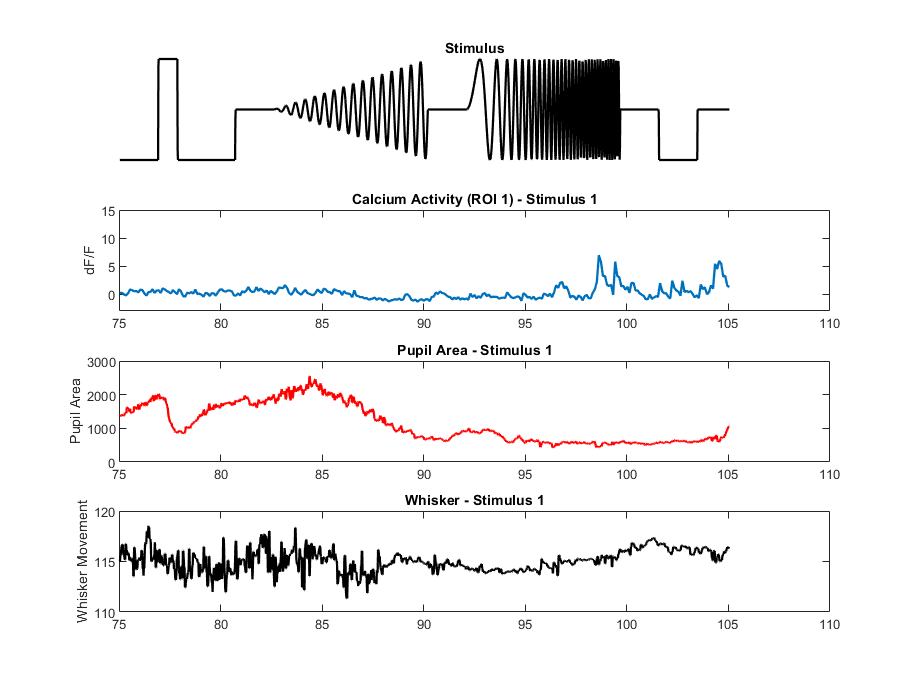

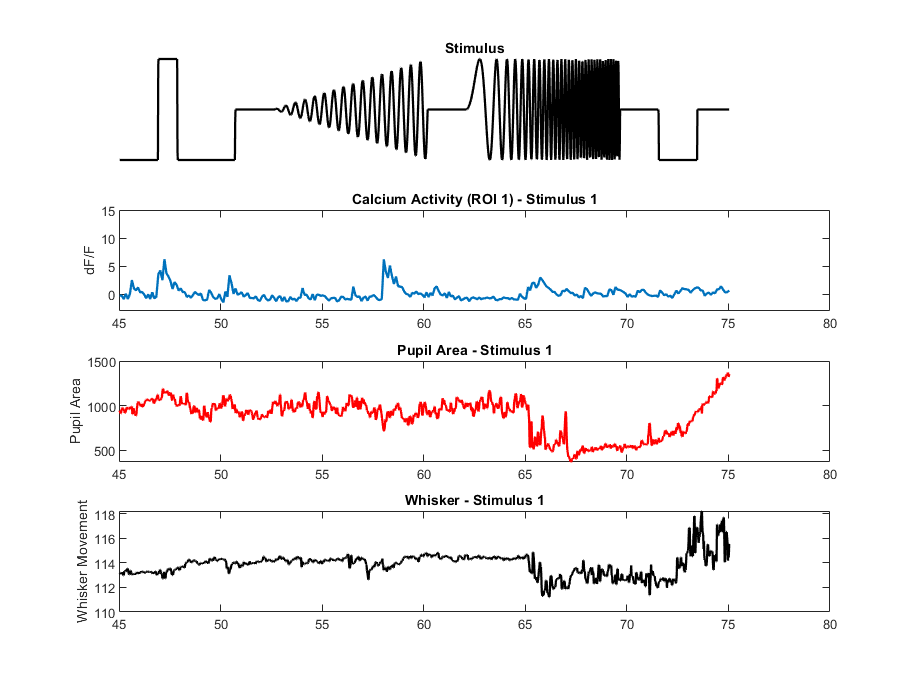

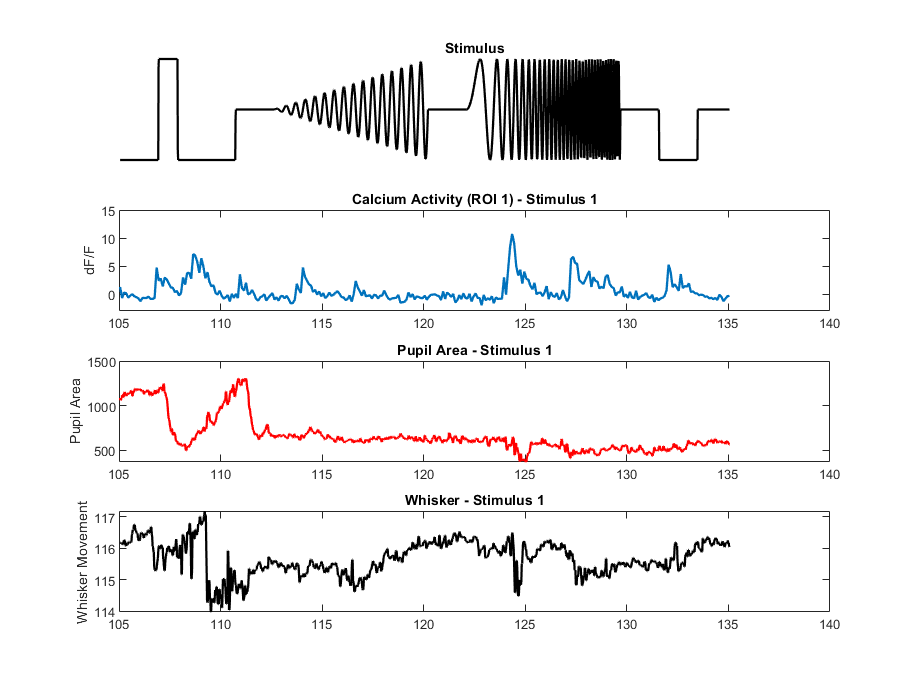

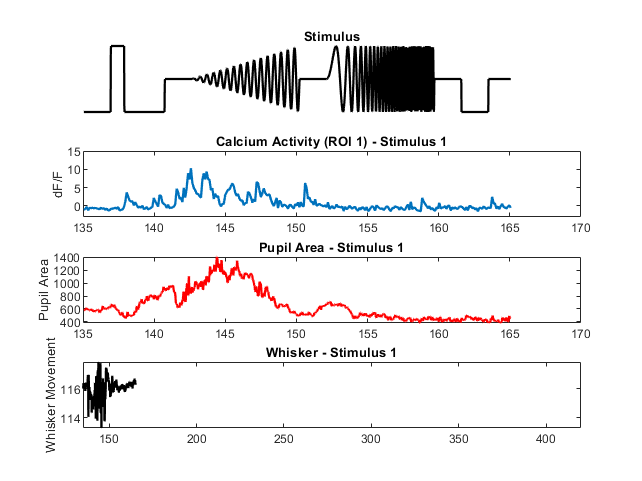



num_stimuli = length(data.Stimuli); % Number of stimuli
trial_number = 5; 

for stim_idx = 1:num_stimuli
    for trial_times =1:trial_number
        % Get stimulus timing
        trial_time = data.Stimuli(stim_idx).stimulus_trial_t;
        stim_start = data.Stimuli(stim_idx).TrialTimes{1, trial_times}(1);
        stim_end = stim_start + trial_time;
    
        % Find frames of calcium for defined stimulus timing
        Ca_index = find(data.TimeCa(1, :) > stim_start & data.TimeCa(1, :) < stim_end);
        Ca_selected = data.CaData(1).Ca_dFF(4, Ca_index);
        
        %z-score and apply moving mean
        %Ca_selected = (Ca_selected - mean(Ca_selected)) / std(Ca_selected);
    
        % Find behavior data for defined stimulus timing
        Beh_index = find(data.Triggers.TimeCamera > stim_start & data.Triggers.TimeCamera < stim_end);
        Beh_selected = data.Behav.PupilArea(Beh_index);
        Whisker_selected = data.Behav.whiskerFollicleA1(Beh_index, 1);

        %z-score and apply moving mean
       % Beh_selected = (Beh_selected - mean(Beh_selected)) / std(Beh_selected);
       % Whisker_selected = (Whisker_selected - mean(Whisker_selected)) / std(Whisker_selected);

        
        % Find locomotion data for defined stimulus timing
        Loc_index = find(data.Triggers.TimeBall{stim_idx *2} > stim_start & data.Triggers.TimeBall{stim_idx *2} < stim_end);
        Loc_time = data.Triggers.TimeBall{stim_idx *2}(Loc_index); % Extract timestamps
        Loc_position = data.LocomotionCal(1).Forward_mm(Loc_index); % Extract position
    
        % Compute locomotion speed (mm/s)
        if length(Loc_time) > 1
            Loc_velocity = diff(Loc_position) ./ diff(Loc_time); 
            Loc_time_velocity = Loc_time(1:end-1); % Adjust time vector for velocity
        else
            Loc_velocity = zeros(1, length(Loc_time)); % Avoid errors if no movement
            Loc_time_velocity = Loc_time;
        end
        
        % Interpolate locomotion velocity to match calcium time vector
        if length(Loc_time_velocity) > 1
            Loc_velocity_resampled = interp1(Loc_time_velocity, Loc_velocity, time_vector, 'linear', 'extrap');
        else
            Loc_velocity_resampled = zeros(size(time_vector)); % No movement case
        end
  
        % Create time vector for consistent x-axis across all plots
        time_vector = linspace(stim_start, stim_end, size(Ca_selected,2));
    
        % Create a new figure for each stimulus
        figure('Name', sprintf('Stimulus %d', stim_idx));
    
        %plot the stimulus
        subplot(4,1,1);
        plot(linspace(stim_start, stim_end, length(fff_brightness)), fff_brightness, 'k', 'LineWidth', 1.5);
        title ("Stimulus")
        axis off; 
        set(gca, 'Box', 'off');          
        
        % Plot calcium data 
        subplot(4,1,2);
        plot(time_vector, Ca_selected(:,:), 'LineWidth', 1.5);
        title(sprintf('Calcium Activity (ROI 1) - Stimulus %d', stim_idx));
        ylabel('dF/F');
        ylim([-3 15]);
        ax1 = gca; % Save axis handle for linking
    
   
        % Plot behavioral data (Pupil Area)
        subplot(4,1,3);
        plot(linspace(stim_start, stim_end, length(Beh_selected)), Beh_selected, 'r', 'LineWidth', 1.5);
        title(sprintf('Pupil Area - Stimulus %d', stim_idx));
        ylabel('Pupil Area');
        ax2 = gca; % Save axis handle for linking
        
        
        % Plot behavioral data (Whisker Movement)
        subplot(4,1,4);
        plot(linspace(stim_start, stim_end, length(Whisker_selected)), Whisker_selected, 'k', 'LineWidth', 1.5);
        title(sprintf('Whisker - Stimulus %d', stim_idx));
        ylabel('Whisker Movement');
        ax3 = gca; % Save axis handle for linking
        
        
%         % Plot locomotion speed
%         subplot(4,1,4);
%         plot(time_vector, Loc_velocity_resampled, 'k', 'LineWidth', 1.5);
%         title(sprintf('Locomotion Speed - Stimulus %d', stim_idx));
%         xlabel('Time (s)');
%         ylabel('Speed (mm/s)');
%         ax3 = gca; % Save axis handle for linking
        

    
        % Link the x-axes so they zoom/pan together
        linkaxes([ax1, ax2, ax3], 'x');
        
        % Adjust spacing and figure size
        set(gcf, 'Position', [100, 100, 800, 600]); % Make figure larger
    end 
end 

%%Loop through all the stimulus

num_stimuli = length(data.Stimuli); % Number of stimuli

for stim_idx = 1:num_stimuli
    % Get stimulus timing
    stim_total_time = data.Stimuli(stim_idx).stimulus_trial_t * data.Stimuli(stim_idx).trials;
    stim_start = data.Stimuli(stim_idx).TimeStimulusFrame(1);
    stim_end = stim_start + stim_total_time;

    % Find frames of calcium for defined stimulus timing
    Ca_index = find(data.TimeCa(1, :) > stim_start & data.TimeCa(1, :) < stim_end);
    Ca_selected = data.CaData(1).Ca_dFF(:, Ca_index);

    % Find behavior data for defined stimulus timing
    Beh_index = find(data.Triggers.TimeCamera > stim_start & data.Triggers.TimeCamera < stim_end);
    Beh_selected = data.Behav.PupilArea(Beh_index);

    % Find locomotion data for defined stimulus timing
    Loc_index = find(data.Triggers.TimeBall{stim_idx *2} > stim_start & data.Triggers.TimeBall{stim_idx *2} < stim_end);
    Loc_time = data.Triggers.TimeBall{stim_idx *2}(Loc_index); % Extract timestamps
    Loc_position = data.LocomotionCal(1).Forward_mm(Loc_index); % Extract position

    % Compute locomotion speed (mm/s)
    if length(Loc_time) > 1
        Loc_velocity = diff(Loc_position) ./ diff(Loc_time); 
        Loc_time_velocity = Loc_time(1:end-1); % Adjust time vector for velocity
    else
        Loc_velocity = zeros(1, length(Loc_time)); % Avoid errors if no movement
        Loc_time_velocity = Loc_time;
    end

    % Create time vector for consistent x-axis across all plots
    time_vector = linspace(stim_start, stim_end, size(Ca_selected,2));

    % Create a new figure for each stimulus
    figure('Name', sprintf('Stimulus %d', stim_idx));

    % Plot calcium data (first ROI only)
    subplot(3,1,1);
    plot(time_vector, Ca_selected(4,:), 'LineWidth', 1.5);
    title(sprintf('Calcium Activity (ROI 1) - Stimulus %d', stim_idx));
    ylabel('dF/F');
    ylim([-3 15]);
    ax1 = gca; % Save axis handle for linking

    % Plot behavioral data (Pupil Area)
    subplot(3,1,2);
    plot(linspace(stim_start, stim_end, length(Beh_selected)), Beh_selected, 'r', 'LineWidth', 1.5);
    title(sprintf('Pupil Area - Stimulus %d', stim_idx));
    ylabel('Pupil Area');
    ax2 = gca; % Save axis handle for linking

    % Interpolate locomotion velocity to match calcium time vector
    if length(Loc_time_velocity) > 1
        Loc_velocity_resampled = interp1(Loc_time_velocity, Loc_velocity, time_vector, 'linear', 'extrap');
    else
        Loc_velocity_resampled = zeros(size(time_vector)); % No movement case
    end

    % Plot locomotion speed
    subplot(3,1,3);
    plot(time_vector, Loc_velocity_resampled, 'k', 'LineWidth', 1.5);
    title(sprintf('Locomotion Speed - Stimulus %d', stim_idx));
    xlabel('Time (s)');
    ylabel('Speed (mm/s)');
    ax3 = gca; % Save axis handle for linking

    % Link the x-axes so they zoom/pan together
    linkaxes([ax1, ax2, ax3], 'x');

    % Adjust spacing and figure size
    set(gcf, 'Position', [100, 100, 800, 600]); % Make figure larger
end


dFF_norm = (dFF - min(dFF,[],2)) ./ (max(dFF,[],2) - min(dFF,[],2)) .* max(dFF,[],2);


% Get stimulus timing
trial_time = data.Stimuli(2).stimulus_trial_t;
stim_start = data.Stimuli(2).TrialTimes{1, 2}(1);
stim_end = stim_start + trial_time;
    
% Find frames of calcium for defined stimulus timing
Ca_index = find(data.TimeCa(1, :) > stim_start & data.TimeCa(1, :) < stim_end)
Ca_selected = dFF_norm(:, Ca_index);

[~, sort_idx] = sort(max(Ca_selected, [], 2), 'descend'); % Change to 'ascend' if you want lowest to highest
Ca_selected = Ca_selected(sort_idx, :);
    
% Find behavior data for defined stimulus timing
Beh_index = find(data.Triggers.TimeCamera > stim_start & data.Triggers.TimeCamera < stim_end);
Pupil_selected = data.Behav.PupilArea(Beh_index);
Whisker_selected = data.Behav.whiskerFollicleA1(Beh_index, 1);

Pupil_selected_norm = (Pupil_selected - min(Pupil_selected)) / (max(Pupil_selected) - min(Pupil_selected));
Whisker_selected_norm = (Whisker_selected - min(Whisker_selected)) / (max(Whisker_selected) - min(Whisker_selected));


% Create time vector for consistent x-axis across all plots
time_vector = linspace(stim_start, stim_end, size(Ca_selected,2));
    
% Create a figure with two subplots
figure;

% === Calcium Activity Heatmap ===

%plot the stimulus
subplot(3,1,1);
plot(linspace(stim_start, stim_end, length(fff_brightness)), fff_brightness, 'k', 'LineWidth', 1.5);
title ("Stimulus")
axis off; 
set(gca, 'Box', 'off');  

subplot(3,1,2); % 
imagesc(time_vector, [1 size(Ca_selected,1)], Ca_selected); % Use the time_vector
colormap turbo;
xlabel('Time (s)');
ylabel('Neuron #');
title('Calcium Activity Heatmap');


% === Subplot 2: Pupil and Whisker Traces ===
subplot(3,1,3); 
axis off; 
set(gca, 'Box', 'off');  
hold on;
plot(linspace(stim_start, stim_end, length(Pupil_selected)), Pupil_selected_norm, 'k', 'LineWidth', 1); 
plot(linspace(stim_start, stim_end, length(Whisker_selected)), Whisker_selected_norm, 'r', 'LineWidth', 1);
hold off;


Computing correlations

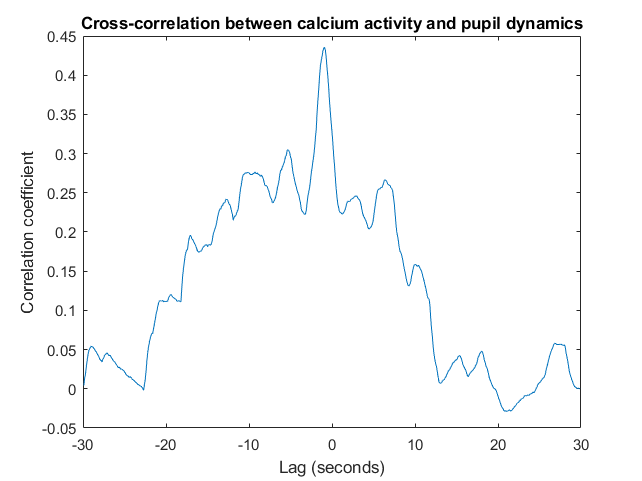

%computing correlations

trial_time = data.Stimuli(2).stimulus_trial_t;
stim_start = data.Stimuli(2).TrialTimes{1, 2}(1);
stim_end = stim_start + trial_time;

%for the whole stimulus 

% size(Beh_selected);
% Ca_sel = Ca_selected(4,:);
% 
% [p, q] = rat(10/50);  % p/q = 1/5
% pupil_data_resampled = resample(Beh_selected, p, q);
% 
% min_length = min(length(Ca_sel), length(pupil_data_resampled));
% calcium_data_trimmed = Ca_sel(1:min_length);
% pupil_data_trimmed = pupil_data_resampled(1:min_length);
% 
% 
% [r, lags] = xcorr(calcium_data_trimmed, pupil_data_resampled, 'coeff');

%for individual trials 

%num_stimuli = length(data.Stimuli); % Number of stimuli

% Get stimulus timing

trial_number = 5; 
Ca_traces = struct(); 

%for stim_idx = 1:num_stimuli
 for trial_times =1:trial_number
    % Get stimulus timing
    trial_time = data.Stimuli(2).stimulus_trial_t;
    stim_start = data.Stimuli(2).TrialTimes{1, trial_times}(1);
    stim_end = stim_start + trial_time;
    
%     stim_start = stim_start + 2; % Add 2 seconds to start
%     stim_end = stim_end - 2;     % Subtract 2 seconds from end

    % Find frames of calcium for defined stimulus timing
    Ca_index = find(data.TimeCa(1, :) > stim_start & data.TimeCa(1, :) < stim_end);
    Ca_selected = data.CaData(1).Ca_dFF(:, Ca_index);

    % Find behavior data for defined stimulus timing
    Beh_index = find(data.Triggers.TimeCamera > stim_start & data.Triggers.TimeCamera < stim_end);
    Beh_selected = data.Behav.PupilArea(Beh_index);
    
    % Store calcium trace for this trial
    Ca_traces.(['trial_', num2str(trial_times)]) = Ca_selected;
    Beh_traces.(['trial_', num2str(trial_times)]) = Beh_selected;  
    
end 
%end 

Beh_selected = Beh_traces.trial_2;    
Ca_sel = Ca_traces.trial_2(4,:);

% stimulus intensity vector 

[p, q] = rat(10/50);  % p/q = 1/5

pupil_data_resampled = resample(Beh_selected, p, q);

min_length = min(length(Ca_sel), length(pupil_data_resampled));
calcium_data_trimmed = Ca_sel(1:min_length);
pupil_data_trimmed = pupil_data_resampled(1:min_length);

% z-score signals
calcium_norm = (calcium_data_trimmed - mean(calcium_data_trimmed)) / std(calcium_data_trimmed);
pupil_norm = (pupil_data_trimmed - mean(pupil_data_trimmed)) / std(pupil_data_trimmed);

%smooth using mean
calcium_norm = movmean(calcium_norm, 10);
pupil_norm = movmean(pupil_norm, 10);

% Calculate cross-correlation
[r, lags] = xcorr(calcium_data_trimmed, pupil_data_trimmed, 'coeff');

% Plot results
figure;
plot(lags/10, r);  % Convert lags to seconds
xlabel('Lag (seconds)');
ylabel('Correlation coefficient');
title('Cross-correlation between calcium activity and pupil dynamics');

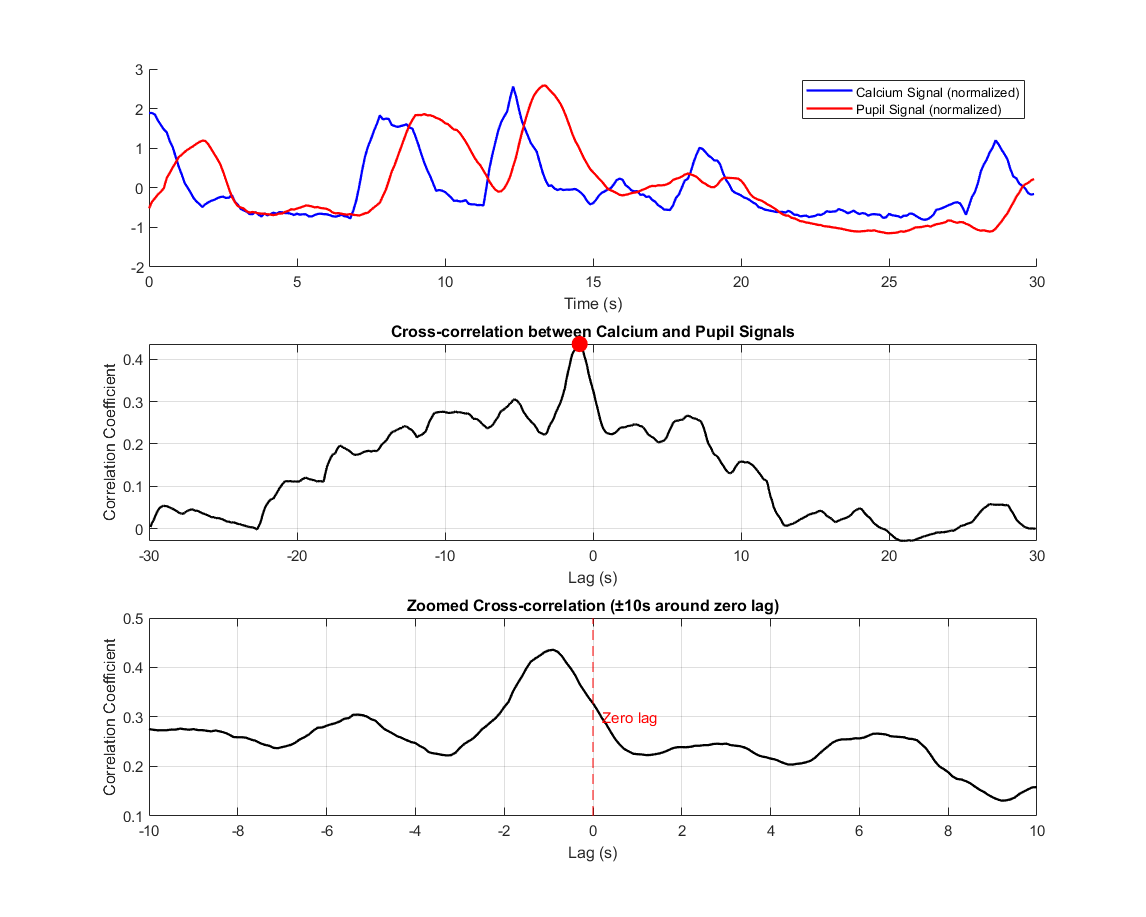


% Create figure with subplots
figure('Position', [100, 100, 1000, 800]);

% Plot 1: Original signals (time-aligned and normalized)
subplot(3,1,1);
t_calcium = (0:length(calcium_norm)-1)/10; % Time in seconds
plot(t_calcium, calcium_norm, 'b', 'LineWidth', 1.5);
hold on;
plot(t_calcium, pupil_norm, 'r', 'LineWidth', 1.5);
legend('Calcium Signal (normalized)', 'Pupil Signal (normalized)');
xlabel('Time (s)');
% ylim([0 1]);
set(gca, 'Box', 'off');  

% Plot 2: Cross-correlation function
subplot(3,1,2);
lag_time = lags/10; % Convert lags to seconds
plot(lag_time, r, 'k', 'LineWidth', 1.5);
title('Cross-correlation between Calcium and Pupil Signals');
xlabel('Lag (s)');
ylabel('Correlation Coefficient');
grid on;

% Find and mark the peak correlation
[max_corr, max_idx] = max(abs(r));
lag_max = lag_time(max_idx);
hold on;
plot(lag_max, r(max_idx), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
%text(lag_max, r(max_idx), ['  Peak: ' num2str(r(max_idx), '%.3f') ' at lag = ' num2str(lag_max, '%.2f') 's'], 'VerticalAlignment', 'bottom');

% Plot 3: Zoomed view of cross-correlation around zero lag
subplot(3,1,3);
% Define range to zoom (e.g., ±10 seconds around zero)
zoom_range = 10; % seconds
zoom_indices = find(lag_time >= -zoom_range & lag_time <= zoom_range);
plot(lag_time(zoom_indices), r(zoom_indices), 'k', 'LineWidth', 1.5);
title('Zoomed Cross-correlation (±10s around zero lag)');
xlabel('Lag (s)');
ylabel('Correlation Coefficient');
grid on;

% Add zero lag line for reference
hold on;
line([0 0], ylim, 'Color', 'r', 'LineStyle', '--');
text(0.2, mean(ylim), 'Zero lag', 'Color', 'r');

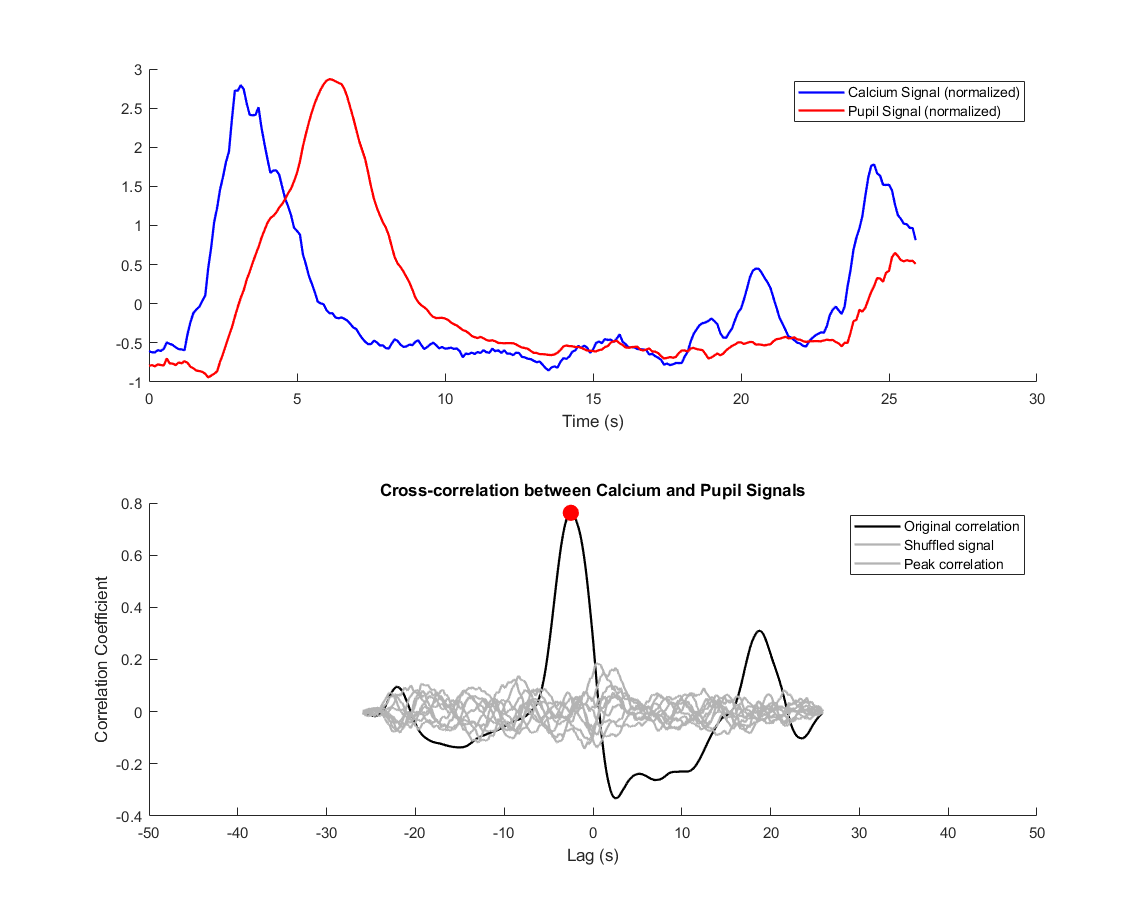

% 1. Calculate the actual correlation
calcium_norm = (calcium_data_trimmed - mean(calcium_data_trimmed)) / std(calcium_data_trimmed);
pupil_norm = (pupil_data_trimmed - mean(pupil_data_trimmed)) / std(pupil_data_trimmed);

calcium_norm = movmean(calcium_norm, 10);
pupil_norm = movmean(pupil_norm, 10);

[r_actual, lags] = xcorr(calcium_norm, pupil_norm, 'coeff');
max_actual_corr = max(abs(r_actual));
lag_at_max = lags(find(abs(r_actual) == max_actual_corr, 1));

% 2. Perform permutation test
num_permutations = 10;  
max_shuffled_corrs = zeros(num_permutations, 1);

%shuffle pupil 
for i = 1:num_permutations
    % Shuffle the pupil data randomly
    pupil_shuffled = pupil_norm(randperm(length(pupil_norm)));
    
    % Calculate cross-correlation with shuffled data
    [r_shuffled, ~] = xcorr(calcium_norm, pupil_shuffled, 'coeff');
    
    % Store maximum correlation for this permutation
    max_shuffled_corrs(i) = max(abs(r_shuffled));
end

% 3. Calculate p-value
% Count how many permutations produced a correlation as high or higher than the actual
p_value = sum(max_shuffled_corrs >= max_actual_corr) / num_permutations;

% Find the maximum correlation and its lag
[max_actual_corr, max_idx] = max(abs(r_actual));
lag_at_max = lags(max_idx);
max_r_value = r_actual(max_idx);  % Get the actual correlation value (not just abs)

% 4. Visualize results
figure('Position', [100, 100, 1000, 800]);

subplot(2,1,1);
t_calcium = (0:length(calcium_norm)-1)/10; % Time in seconds
plot(t_calcium, calcium_norm, 'b', 'LineWidth', 1.5);
hold on;
plot(t_calcium, pupil_norm, 'r', 'LineWidth', 1.5);
legend('Calcium Signal (normalized)', 'Pupil Signal (normalized)');
xlabel('Time (s)');
% ylim([0 1]);
set(gca, 'Box', 'off');  


% Original cross-correlation plot
subplot(2,1,2);
lag_time = lags/10; % Convert lags to seconds
plot(lag_time, r_actual, 'k', 'LineWidth', 1.5);
title('Cross-correlation between Calcium and Pupil Signals');
xlabel('Lag (s)');
ylabel('Correlation Coefficient');
set(gca, 'Box', 'off');  
hold on;

% Create confidence bands at each lag point
shuffled_corrs_at_lags = zeros(num_permutations, length(lags));
for i = 1:num_permutations
    pupil_shuffled = pupil_norm(randperm(length(pupil_norm))); % Changed from randsample to randperm for consistency
    [shuffled_corrs_at_lags(i,:), ~] = xcorr(calcium_norm, pupil_shuffled, 'coeff');
end

plot(lag_time, shuffled_corrs_at_lags, 'Color', [.7 .7 .7], 'LineWidth', 1.5);


% Plot percentile bounds of shuffled correlations (e.g., 95% confidence interval)
upper_bound = prctile(shuffled_corrs_at_lags, 97.5, 1);
lower_bound = prctile(shuffled_corrs_at_lags, 2.5, 1);
% fill([lag_time, fliplr(lag_time)], [upper_bound, fliplr(lower_bound)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');

% Plot the peak correlation point
plot(lag_at_max/10, max_r_value, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
xlim([-50, 50]);
legend('Original correlation', 'Shuffled signal', 'Peak correlation');

% Calculate R-squared between calcium and pupil signals
calcium_norm = (calcium_data_trimmed - mean(calcium_data_trimmed)) / std(calcium_data_trimmed);
pupil_norm = (pupil_data_trimmed - mean(pupil_data_trimmed)) / std(pupil_data_trimmed);
pupil_norm = pupil_norm';

% Calculate actual R-squared values at different lags
max_lag = 50; % Adjust based on your data
[r_squared_actual, lags] = xcorr_r_squared(calcium_norm, pupil_norm, max_lag);
max_actual_r_squared = max(r_squared_actual);
lag_at_max = lags(find(r_squared_actual == max_actual_r_squared, 1));

% Perform permutation test
num_permutations = 5000;
max_shuffled_r_squared = zeros(num_permutations, 1);

for i = 1:num_permutations
    % Shuffle the pupil data randomly
    pupil_shuffled = pupil_norm(randperm(length(pupil_norm)));
    
    % Calculate R-squared with shuffled data
    [r_squared_shuffled, ~] = xcorr_r_squared(calcium_norm, pupil_shuffled, max_lag);
    
    % Store maximum R-squared for this permutation
    max_shuffled_r_squared(i) = max(r_squared_shuffled);
end

% Calculate p-value using the Laplace correction
p_value = (sum(max_shuffled_r_squared >= max_actual_r_squared) + 1) / (num_permutations + 1);

% Calculate Z-score
z_score = (max_actual_r_squared - mean(max_shuffled_r_squared)) / std(max_shuffled_r_squared);

% Visualize results
figure('Position', [100, 100, 1000, 800]);

% Plot R-squared values at different lags
subplot(2,1,1);
lag_time = lags/10; % Convert lags to seconds (assuming 10Hz sampling)
plot(lag_time, r_squared_actual, 'k', 'LineWidth', 1.5);
title(['R-squared between Calcium and Pupil Signals (p = ' num2str(p_value, '%.4e') ', Z = ' num2str(z_score, '%.2f') ')']);
xlabel('Lag (s)');
ylabel('R-squared');
grid on;
hold on;

% Plot the peak R-squared point
plot(lag_at_max/10, max_actual_r_squared, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
text(lag_at_max/10, max_actual_r_squared, ['  Max R² = ' num2str(max_actual_r_squared, '%.3f') ' at lag = ' num2str(lag_at_max/10, '%.2f') 's'], 'VerticalAlignment', 'bottom');

% Plot histogram of permutation results
subplot(2,1,2);
histogram(max_shuffled_r_squared, 30, 'Normalization', 'probability');
hold on;
xline(max_actual_r_squared, 'r', 'LineWidth', 2);
title(['Distribution of Maximum R-squared Under Null Hypothesis']);
xlabel('Maximum R-squared');
ylabel('Probability');

% Try fitting extreme value distribution for better p-value estimation
    pd = fitdist(max_shuffled_r_squared, 'GeneralizedExtremeValue');
    p_value_fitted = 1 - cdf(pd, max_actual_r_squared);
    fprintf('P-value from fitted distribution: %e\n', p_value_fitted);

P-value from fitted distribution: 1.389333e-12


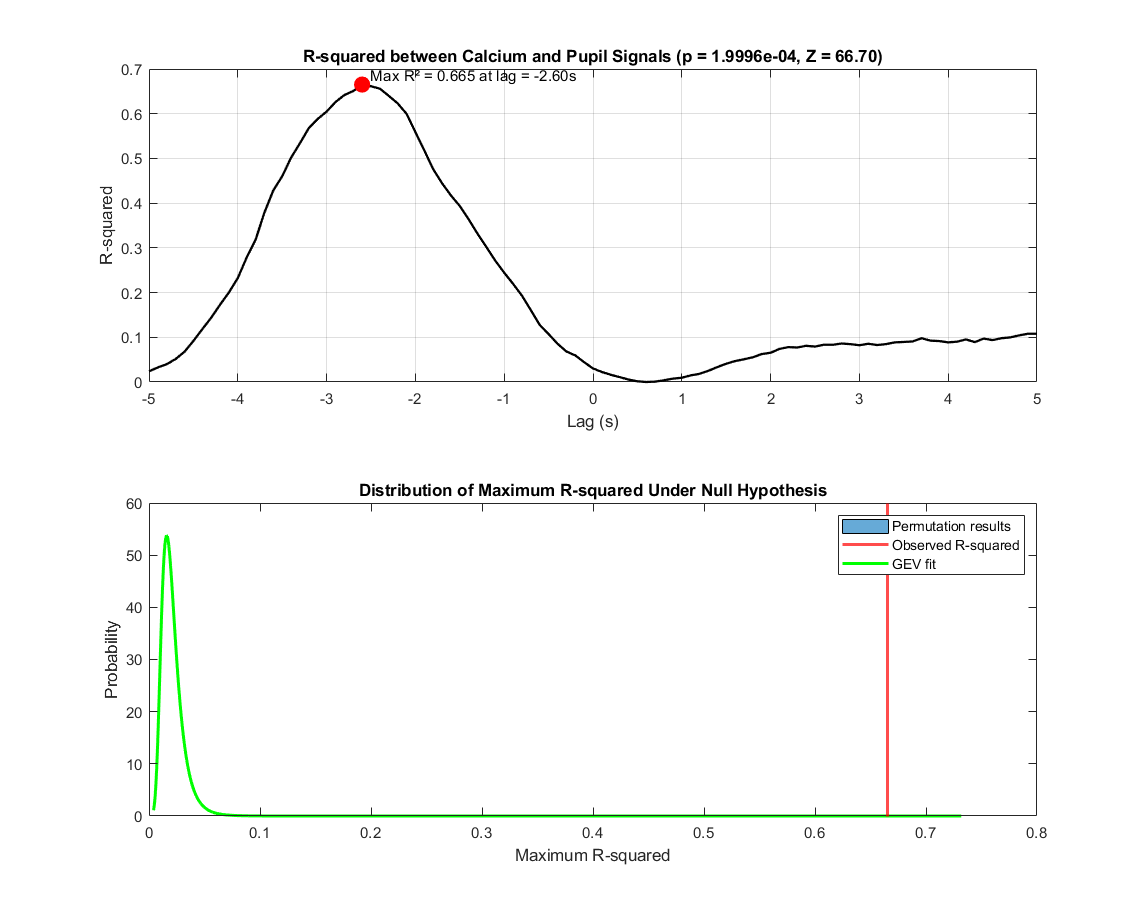

    
    % Plot the fitted distribution
    x = linspace(min(max_shuffled_r_squared), max(max_actual_r_squared*1.1, max(max_shuffled_r_squared)), 1000);
    y = pdf(pd, x);
    plot(x, y, 'g-', 'LineWidth', 2);
    legend('Permutation results', 'Observed R-squared', 'GEV fit');

% Load pupil area from your data
pupil_area = data.Behav.PupilArea;

% Create appropriate time vectors for both original and downsampled data
t_original = (1:length(pupil_area)) / 50;  
t_downsampled = (1:size(dFF,2)) / 10;      

% Downsample pupil size using interpolation
pupil_downsampled = interp1(t_original, pupil_area, t_downsampled, 'linear');

% Z-score the downsampled pupil data
pupil_z = (pupil_downsampled - mean(pupil_downsampled)) / std(pupil_downsampled);

% Check if z-scoring worked correctly
disp(['Mean of z-scored pupil: ' num2str(mean(pupil_z))]);
disp(['Std of z-scored pupil: ' num2str(std(pupil_z))]);

% Z-score the calcium data (dFF)
dFF_z = (dFF - mean(dFF, 2)) ./ std(dFF, 0, 2); 

% Plot 1: Original vs Downsampled (raw values)
figure;
subplot(2,1,1);
plot(t_original, pupil_area, 'r', 'LineWidth', 1); hold on;
plot(t_downsampled, pupil_downsampled, 'b', 'LineWidth', 2);
xlabel('Time (seconds)'); 
ylabel('Pupil Area (raw)');
legend('Original Pupil Area (60 Hz)', 'Downsampled Pupil Area (10 Hz)');
title('Raw Pupil Area: Original vs Downsampled');

% Plot 2: Z-scored downsampled pupil data (in separate figure to ensure it works)
figure;
plot(t_downsampled, pupil_z, 'b', 'LineWidth', 2);
xlabel('Time (seconds)'); 
ylabel('Pupil Area (z-scored)');
title('Z-scored Downsampled Pupil Area');

% Load pupil area from your data
pupil_area = data.Behav.PupilArea;

% Create appropriate time vectors for both original and downsampled data
t_original = (1:length(pupil_area)) / 60;  % Time in seconds for 60 Hz data
t_downsampled = (1:size(dFF,2)) / 10;      % Time in seconds for 10 Hz data

% Downsample pupil size using interpolation
pupil_downsampled = interp1(t_original, pupil_area, t_downsampled, 'linear');

% Normalize (Z-score) if needed
pupil_z = (pupil_downsampled - mean(pupil_downsampled)) / std(pupil_downsampled); 
dFF_z = (dFF - mean(dFF, 2)) ./ std(dFF, 0, 2); 

% Plot both original and downsampled data
figure;
plot(t_original, pupil_area, 'k', 'LineWidth', 1); hold on;
plot(t_downsampled, pupil_downsampled, 'b', 'LineWidth', 1);
xlabel('Time (seconds)'); 
ylabel('Pupil Area');
legend('Original Pupil Area (60 Hz)', 'Downsampled Pupil Area (10 Hz)');
title('Comparison of Original and Downsampled Pupil Area');
hold off;

## Extracting Timing

% Define stimulus time window
fs = 60;
num_trials = data.Stimuli.trials;
trial_duration = 30; 
stim_total_time = trial_duration * num_trials; 

start_time = data.Stimuli(1).TimeStimulusFrame(1);
end_time = start_time + stim_total_time;
[~, start_indx] = min(abs(data.TimeCa(2,:) - start_time));
[~, end_indx]   = min(abs(data.TimeCa(2,:) - end_time));

dFF = data.CaData(1).Ca_dFF;
time_Ca = data.TimeCa(2,:);
dFF_norm = (dFF - min(dFF, [], 2)) ./ (max(dFF, [], 2) - min(dFF, [], 2));
roi_indices = 1:11;
num_trials = data.Stimuli.trials;
start_time = data.Stimuli(1).TimeStimulusFrame(1);
end_time = start_time + stim_total_time;
[~, start_indx] = min(abs(data.TimeCa(2,:) - start_time));
[~, end_indx]   = min(abs(data.TimeCa(2,:) - end_time));
    
dFF_norm_selected = dFF_norm(roi_indices,  start_indx:end_indx);

**Plotting Heatmap with traces**

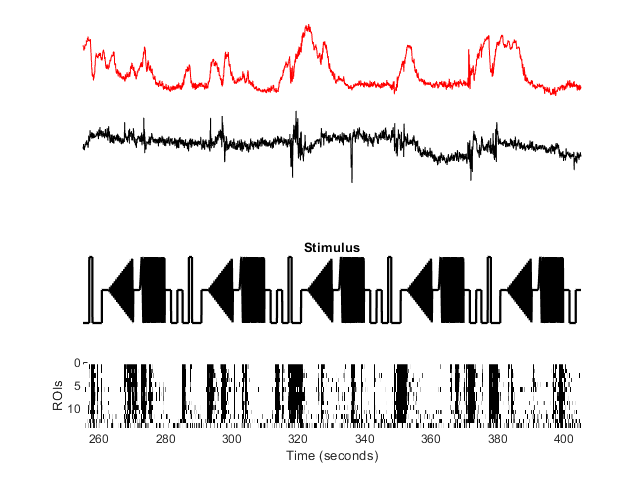


stim_total_time = data.Stimuli(2).stimulus_trial_t * data.Stimuli(2).trials;
stim_start = data.Stimuli(2).TimeStimulusFrame(1);
stim_end = stim_start + stim_total_time;

% Find frames of calcium for defined stimulus timing
Ca_index = find(data.TimeCa(1, :) > stim_start & data.TimeCa(1, :) < stim_end);
Ca_selected = data.CaData(1).Ca_dFF(:, Ca_index);

% Find behavior data for defined stimulus timing
Beh_index = find(data.Triggers.TimeCamera > stim_start & data.Triggers.TimeCamera < stim_end);
Beh_selected = data.Behav.PupilArea(Beh_index);

[~, sort_idx] = sort(max(Ca_selected, [], 2), 'descend'); % Change to 'ascend' if you want lowest to highest

Ca_selected = Ca_selected(sort_idx, :);

%dFF_norm_selected = (Ca_selected - mean(Ca_selected, 2)) ./ std(Ca_selected, 0, 2);
dFF_norm_selected = (Ca_selected - mean(Ca_selected, 2)) ./ std(Ca_selected, 0, 2)  .* max(Ca_selected,[],2);



% Create a figure with two vertically stacked subplots
figure;
subplot(4,1,1)
plot(linspace(stim_start, stim_end, length(Beh_selected)), Beh_selected, 'r');
axis off; 
xlim([stim_start, stim_end])
set(gca, 'Box', 'off');
set(gca, 'Position', [0.13 0.80 0.775 0.15]);

subplot(4,1,2)

Whisker_selected = data.Behav.whiskerFollicleA1(Beh_index, 1);
Whisker_selected_norm = (Whisker_selected - mean(Whisker_selected)) / std(Whisker_selected);
plot(linspace(stim_start, stim_end, length(Whisker_selected_norm)), Whisker_selected_norm, 'k')
axis off; 
xlim([stim_start, stim_end])
set(gca, 'Box', 'off');  
set(gca, 'Position', [0.13 0.62 0.775 0.15]);

subplot(4,1,3)

num_repeats = 5;  % Number of stimulus repetitions
fff_brightness_repeated = repmat(fff_brightness, 1, num_repeats); 
plot(linspace(stim_start, stim_end, length(fff_brightness_repeated)), fff_brightness_repeated, 'k', 'LineWidth', 1.5);
title ("Stimulus")
axis off; 
set(gca, 'Box', 'off');          
xlim([stim_start, stim_end])
        
subplot(4,1,4)

original_colormap = gray;  % Get the default gray colormap
reversed_colormap = flipud(original_colormap);
imagesc('XData',linspace(stim_start, stim_end, size(dFF_norm_selected, 2)), 'CData', dFF_norm_selected)
colormap(reversed_colormap);
caxis([0 3])
set(gca, 'YDir', 'reverse');
xlim([stim_start, stim_end])
xlabel('Time (seconds)'); 
ylabel('ROIs');